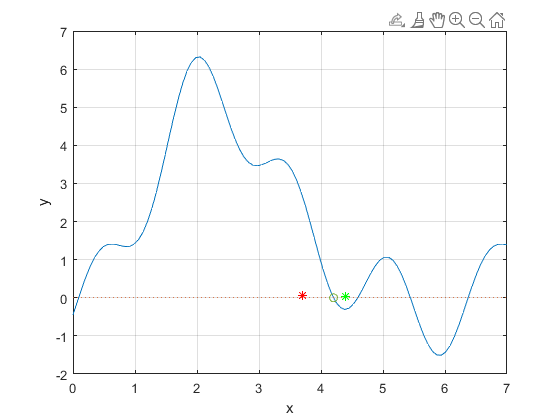

% initial params
a = 0;
b = 7;
x = linspace(a,b,100);

% identifying function
f = @(x) 1 + (1 + sin(x) - cos(x)).^2 - (sin(2*x) - cos(2*x) - 0.2).^2;

plot(x, f(x), x, 0*x, ':')
grid on
xlabel('x');
ylabel('y');

z1 = ginput(1);
a = z1(1);
z2 = ginput(1);
b = z2(1);

hold on
plot(z1(1),z1(2),'r*',z2(1),z2(2),'g*')
hold off

eps = 1e-6;
iter = 0;

if f(a)*f(b) > 0
    disp('Wrong points!');
else
    while abs(a-b) > eps
        z = (a+b)/2;
    
        if f(z)*f(a) < 0
            b = z;
        else
            a = z;
        end
    
         iter = iter+1;
    end
end

hold on
plot(z,f(z),'-o')
hold off